# ECSE 343: Numerical Methods for Engineers- Assignement 2

Due Date: 11 November 2021

Student Name:

Student ID:    

#### Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

#### Please submit this **.mlx** file along with the **PDF** copy of this file.

## Question 1: 

a) Given the equation $x^2 + 2 bx  -1=0$ where $b$ is a parameter chosen such that $b> 0$. Using the quadratic formula the roots $x_1$ and $x_2$ of this equation are given by $x=-b\pm\sqrt{b^2 +1}$ . The following MATLAB program computes and plots the roots $x_1$ and $x_2$ as a function of $b$ for 1000 logarithmically spaced values of $b$ between ${10}^6$ and ${10}^8$. Run the code and explain the reason why there are discontinuities.

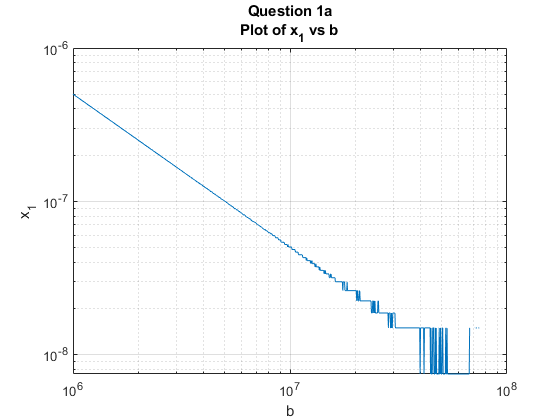



b = logspace(6,8,1000);

x1 = -b+sqrt(b.^2 +1);
x2 = -b-sqrt(b.^2 +1);



%plot x1 on a loglog scale

figure
loglog(b,x1)
title({'Question 1a';'Plot of x_1 vs b'})
xlabel('b')
ylabel('x_1')
grid on

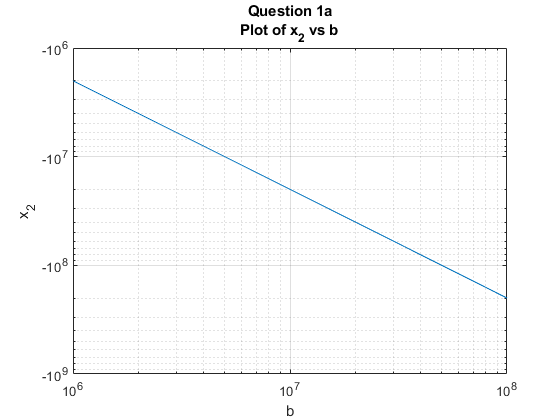



%plot x2 on a loglog scale

figure
loglog(b,x2)
xlabel('b')
ylabel('x_2')
title({'Question 1a';'Plot of x_2 vs b'})
grid on

b)  For the part a) one of the obtained roots is $x_1 = -b + \sqrt {b^2 +1}$ .  When using 64-bit IEEE number representation (double precision) what is  the smallest value of  $b$  the result of the computation $x_1 = -b + \sqrt {b^2 +1}$ produces an answer $x_1 =0$? Explain.

*        % type up your solution here*

c) Prove that the product of roots $x_1x_2=(-b+\sqrt{b^2 +1})(-b-\sqrt{b^2 +1})=-1$ for all $b> 0$.

*    % type up your solution here*

d) Write a script that computes and plots the roots $x_1$ and $x_2$ as a function of $b$ for 1000 logarithmically spaced values of $b$ between ${10}^6$ and ${10}^8$ (same as in part a. above) which does not suffer from numerical illconditioning.

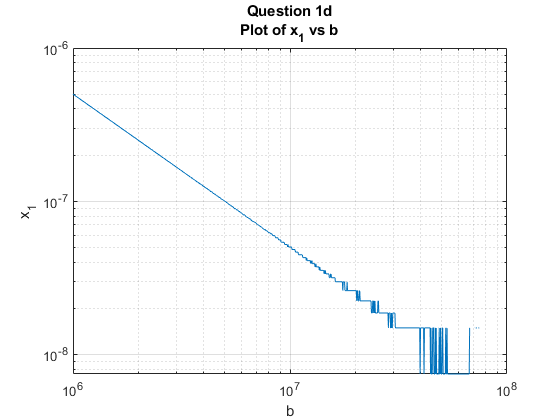

% write your program here 

b = logspace(6,8,1000);

%% Put your code for computing x1 and x2 below



%plot x1 on a loglog scale
figure(1)
loglog(b,x1)
xlabel('b')
ylabel('x_1')
grid on
title({'Question 1d';'Plot of x_1 vs b'})

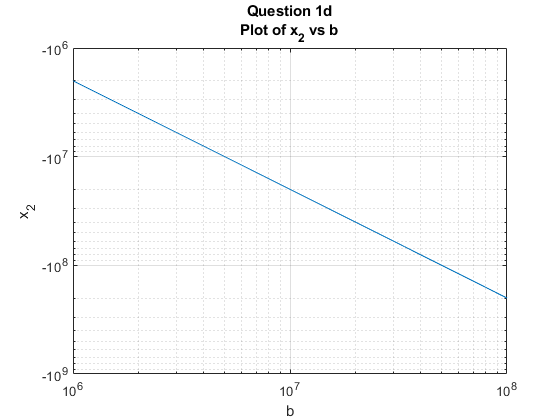


%plot x2 on a loglog scale
figure(2)
loglog(b,x2)
xlabel('b')
ylabel('x_2')
grid on
title({'Question 1d';'Plot of x_2 vs b'})

## Question 2: 

(a) **Cholesky factorization **is an alternative to LU decompostion which can be applied on symmetric positive definite matrices. A symmetric positive definite matrix$\mathit{\mathbf{M}}$must satisfy following two conditions:

     1. The matrix $\mathit{\mathbf{M}}$must be sysmetric, i.e. $\mathit{\mathbf{M}}={\mathit{\mathbf{M}}}^{\mathit{\mathbf{T}}}$

     2. The matrix $\mathit{\mathbf{M}}$ must be positive definite,  i.e.  ${\mathit{\mathbf{x}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{M}}\;\mathit{\mathbf{x}}>0$ for  all  $\mathit{\mathbf{x}}\in \Re^{N\times 1}$except $\left\|\mathit{\mathbf{x}}\right\|\not= 0$.

If the above two conditons are met then the matrix $\mathit{\mathbf{M}}$ can be factored as 


$$\mathit{\mathbf{M}}=\mathit{\mathbf{L}}\;{\mathit{\mathbf{L}}}^T$$
                 

where $\mathit{\mathbf{L}}$ is a $N\times N$the lower triangular matrix with real and positive diagonal enteries. The enteries of matrix $\mathit{\mathbf{L}}$ are given by the following expression 


$$\textbf{L}_{i,j} = 
\begin{cases}
    \sqrt{ \textbf{M}_{j,j} - \sum_{k=1}^{j-1} \textbf{L}_{j,k}^2 }    ,& \text{if  } i =j\\
    \frac{1}{\textbf{L}_{j,j}} \left(\textbf{M}_{i,j} - \sum_{k=1}^{j-1} \textbf{L}_{i,k} \textbf{L}_{j,k} \right),              & \text{if  } i>j\\
0, & \text{otherwise}
\end{cases}$$


The cost of Cholesky factorization algorithm is rougly half than the LU decompostion. Your task is to implement the Cholesky decomposition alogorithm, the use the outline of the function named *CholeskyDecomposition* provided in the appendix.

Use the cell below to test your Cholesky decompostion code by computing the Frobenius norm of  $\left.{\left(\mathit{\mathbf{L}}\right.}^{\;} {\mathit{\mathbf{L}}}^T -M\right)\ldotp$

M= [2 -1 0; -1 2 -1; 0 -1 2];

L = CholeskyDecompositon(M);

Error =  norm(L*L'-M);


 b) In regression problems we ofthen need to solve the normal eqautions,  ${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$.  Show that the matrix $\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$ is symmetric positive definite, and thus can be factored using Cholesky Decomposition.

c) Using Cholesky facotrization scheme $\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$ can be factored as ${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;={\mathit{\mathbf{L}}}^{\;} {\mathit{\mathbf{L}}}^T$. This transforms the normal equation into the form,


$$\mathit{\mathbf{L}}\;{\mathit{\mathbf{L}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$$


The above equation consists of the triangular systems. The solution **x **can be obtained by  first solving $\mathit{\mathbf{L}}\;\mathit{\mathbf{y}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$ using the forward substitution, then by solving the  ${\mathit{\mathbf{L}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{x}}=\mathit{\mathbf{y}}$ using backward subsitution. Implement the Cholesky solver function named *LeastSquareSolver_Cholesky  *for least squares in the function in the appendix.

*Note: for the forward and backward substitution use the functions named ****ForwardSubs**** and**** BackwardSubs**** provided in the appendix.*

Test the your Cholesky Least Saquare solver below.

A = rand(30,15); % random over-determined system
b = ones(30,1)

b =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



x = LeastSquareSolver_Cholesky(A,b);

Output argument "x" (and maybe others) not assigned during call to "Assignment2>LeastSquareSolver_Cholesky".


residual = A*x-b;

Norm_residual = norm(residual);

disp(['Question 2c: The norm of the residual after solving using Cholesky based least sqaure solver is '  num2str(Norm_residual)]);




## Question 3:

a) Show that a good estimate for the condition number of $A^TA$ is $\kappa \;\left(A^{T\;} A\right)\approx {\kappa \left(A\right)}^2 \;$.

*% type your answer here*

b) Given two orthonormal matrices $U$and $Q$, show that product of these matrices, $\textrm{UQ}$, is also orthonormal.

*% type your answer here*

c) If A is an invertible matrix and Q is an orthonormal matrix, show that $\kappa \left(\textrm{QA}\right)=\kappa \left(A\right)\ldotp$

*% type your answer here*

## Question 4:

 In this question we will develop the different algorithms to implment QR factorization.

a)  Use the cell below to implement a function that computes Gram-Schmidt based QR decompositon of a input matrix A.

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

   A = rand(15,6); % A is a 15x6 matrix of random numbers
   [Qgs,Rgs] = gschmidt(A);
   
   %use the norm to check 
   normGS = norm(A-Qgs*Rgs,'fro') ;

b)  Use the cell below to implement a function that uses the Modiefied Gram-Schmidt approach to compute the  QR decompositon of  the input matrix A.

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

   A = rand(15,6); % A is a 15x6 matrix of random numbers
   [Qmgs,Rmgs] = mgschmidt(A);
   
   normMGS = norm(A-Qmgs*Rmgs,'fro');
   
   

c)  Use the cell below to implement a function that uses the Householder approach to compute the  QR decompositon of  the input matrix A.

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

   A = rand(15,6); % A is a 15x6 matrix of random numbers
   [Q,R] = householder(A);
   
   normHH = norm(A-Q*R,'fro');
   
   

d) We know that $\mathit{\mathbf{Q}}$ matrix obtained using QR decompostion should have orthonormal columns i.e. ${\mathit{\mathbf{Q}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{Q}}=\mathit{\mathbf{I}}$. However, due to numerical errors, In this section we will test the functions written above to compare the error between the above implemeneted approaches. In oder to do this we will use a $n\times n$ HIlbert Matrix, the entries of Hibert Matrix are given by 


$$h_{i,j} =\frac{1}{\;i+j-1}$$


 In the cell below we compute the QR decomposition of Hilbert matrices of size ranging from 2 to 16, then we compute the norm of error $\left({\mathit{\mathbf{Q}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{Q}}-\mathit{\mathbf{I}}\right)$ to access the performance of the lorithms written in part (a), ( b), and (c). Comment on the results obtained, which method performs better.

for n=2:19
a= hilb(n); % n is the size of the matrix
[q_gs,r1] = gschmidt(a); %using algorithm classical Gram--Schmidt
[q_mgs,r2] = mgschmidt(a); %using algorithm modified Gram-Schmidt
[q_hh,r3] = householder(a); % using house holder

err_gs(n-1) = norm(q_gs'*q_gs - eye(n),'fro');
err_mgs(n-1) = norm(q_mgs'*q_mgs - eye(n),'fro');
err_hh(n-1) = norm(q_hh'*q_hh - eye(n),'fro');
end 


figure
hold on 
grid on 
plot(2:19,err_gs,'b-d')
plot(2:19,err_mgs,'k-o')
plot(2:19,err_hh,'c-s')
ylabel('Frobenius Norm of error matrix');
xlabel('Matrix Size [n]')
legend('Classical Gram-Schmidt','Modified Gram-Schmidt','Householder');
title({'Question 4d'; 'Comparison of Frobenious Norm for different QR methods'})


## **Question 5: **

Polynomial fitting is one of the many applications of Least-Squares Approximation. Given the experimental data, shown in Table below, 

    
$$\matrix{   Input,, x  | &  x_0  &x_1  & x_2& x_3 &\dots  & x_{m-1}& x_m \cr
Output, y| &  y_0 & y_1& y_2 & y_3 & \dots & y_{m-1}&y_m
}$$


we can fit a $n^{\textrm{th}}$degree polynomial, $p\left(x\right)=a_0 +a_1 x+a_{2\;} x^{2\;} +a_3 x^3 +\cdots +a_{n\;} x^n$. To find the coefficicients,  $\mathit{\mathbf{A}}=\left\lbrack a_{0\;} ,\;\;a_1 ,\;\;a_2 ,\cdots a_n \right\rbrack$, we can solve the linear system shown below. 


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
1 & x_{2\;}  & x_{2\;}^2  & \cdots \; & x_{2\;}^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_{m-1}  & x_{m-1}^2  & \cdots  & x_{m-1}^n \\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{a}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{Y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack } }$$


The system $\mathit{\mathbf{M}}\;\mathit{\mathbf{a}}=\mathit{\mathbf{Y}}$ can then be solved to compute the coefficients in vector $\mathit{\mathbf{a}}\ldotp$

a) Your first task is to write a function that takes the input data vector $\mathit{\mathbf{x}}$ and degree of the polynomial, then returns the polynomial matrix $\mathit{\mathbf{M}}\ldotp$ Complete the function *PolynomialMatrix* in the appendix.

% test your code here by inputing X= [ 1 2 3] for degree 3. 

% You can manually verify if this matrix is implemented correctly.

X= [ 1; 2; 3];
Mtest = PolynomialMatrix(X,3)




b) The least squares method can be used to solve the overdetermined linear system $\mathit{\mathbf{M}}\;\mathit{\mathbf{a}}=\mathit{\mathbf{Y}}$ to obtain the polynomial coefficients. This can be done by directly solving the Normal equations (using cholesky decomposition for example) or by using QR decomposition. In the code below, use the **MATALB's QR decomposition function** to find the polynomial coefficients if we assume a polynomial model of order 1. 

*Note: for the forward and backward substitution use the functions named ****ForwardSubs**** and**** BackwardSubs**** provided in the appendix.*

% Load the Input Data from the provided .mat file 

load('Polynomial_Fitting_Data.mat');

x = x_given;
y = y_given;
deg = 1;

% get Polynomial Matrix 
M = PolynomialMatrix(x,deg);


   
   % MATLAB QR Decomposition
   [Q,R] = qr(Mp);
   
   % Find the polynomial coefficients using Q & R matrices obtained obove.
   % For forward and backward substitution functions use following
   % functions ForwardSubs(), BackwardSubs
     
  
   
   % Name the Coefficeints obtained QR as Ar
            
            % write your code here
   

Now that you have obtained the coefficients for the first order polynomial model, $p\left(x\right)=a_0 +a_1 x$, we can test this model by evaluating $p\left(x\right)$ at different values of $x$ between 0 to 7. **Run the code below and explain the results obtained in the figure. Is this order sufficient?**

   xtest = x;
   
   px = zeros(length(xtest),1);

   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
   end
   %plots
    figure
   hold on
   plot(x,y,'ro')
 plot(x,y,'gd')
   plot(xtest,px,'b-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' Given Data','Used Data','Obtained Model')
   grid on
   title({'Question 5b';'The obtained  model using 1^{st} degree Polynomial'})


c) In this part we will use a higher order model (a polynomial of order 6), but only a limited amount of input data points to generate this model (we will use only** 15 data points)**. Use QR decomposition function to find the polynomial coefficients for the **6th degree polynomial**.  

% Load the Input Data from the provided .mat file 

load('Polynomial_Fitting_Data.mat');

deg = 6; %polynomial degree
x = x_given(1:20:end);  % x has 15 data points!! 
y = y_given(1:20:end);  % y has 15 data points!!

% get Polynomial Matrix 
Mp= PolynomialMatrix(x,deg);


   % MATLAB QR Decomposition
   [Q,R] = qr(Mp);
   
   %--------------------------------------------------------------------------------------------------
   % Find the polynomial coefficients using  Q & R matrices obtained obove.
   
   
   
   % Name the Coefficeints obtained QR as Ar
            
            % write your code here
   
 

We can test this model by evaluating $p\left(x\right)=a_{0\;} +a_1 x+\ldotp \ldotp \ldotp +a_6 x^6$ at different values of $x$ between 0 to 7. **Is this a good model? Comment on the results obtained in figure Question 5c, and explain the cause of what you see.**


   xtest = linspace(0,7,701);
   xtest = xtest';
   powers = 0:deg;
   px = zeros(length(xtest),1);
 
   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
      
   end
   %plots
   figure
   hold on
   plot(x_given,y_given,'ro') % plot all Data
   plot(x,y,'gd') % plot Used Data
   plot(xtest,px,'b-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' All of the Data','Data used','Obtained Model')
   title({'Question 5c';'The obtained  model using 6^{th} degree Polynomial'})
   grid on


d ) In this part we will use a polynomial of order **14,**  again this will be used with limited amount of data (we will use only** 15 data points, same as part c**). Use QR decomposition function to find the polynomial coefficients for the **14th degree polynomial**.  

% Load the Input Data from the provided .mat file 

load('Polynomial_Fitting_Data.mat');

deg =14
x = x_given(1:20:end);  % x has 15 data points!! 
y = y_given(1:20:end);  % y has 15 data points!!

% get Polynomial Matrix 
Mp= PolynomialMatrix(x,deg);


   % MATLAB QR Decomposition
   [Q,R] = qr(Mp);
   
   %--------------------------------------------------------------------------------------------------
   % Find the polynomial coefficients using  Q & R matrices obtained obove.
   
   
   
   % Name the Coefficeints obtained QR as Ar
            
            % write your code here
   
 

We can test this model by evaluating $p\left(x\right)$ at different values of $x$ between 0 to 7. **Is this a good model? Comment on the results obtained in figure Question 5d, and explain the cause of what you see.**


   xtest = linspace(0,7,701);
   xtest = xtest';
   powers = 0:deg;
   px = zeros(length(xtest),1);
 
   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
      
   end
   %plots
   figure('Name','Question 5d','NumberTitle','off')
   hold on
   plot(x_given,y_given,'ro') % plot all Data
   plot(x,y,'gd') % plot Used Data
   plot(xtest,px,'b-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   ylim([-70 70])
   legend(' All of the Data','Data used','Obtained Model')
 title({'Question 5d';'The obtained  model using 14^{th} degree Polynomial'})
   grid on


e)Finally, now will use the various different versions of QR decompositon implemented in earlier questions. Use three versions of the QR decompostion that you implemented in Question 3. We want to fit the **polynomial of degree 59 **through with **60 data** **points**. Clearly show all the plots (with legends) and comment on the results obtained.

% Load the Input Data from the provided .mat file 

load('Polynomial_Fitting_Data.mat');

deg = 59
x = x_given(1:5:end);  % x has 60 data points!! 
y = y_given(1:5:end);  % y has 60 data points!!

% get Polynomial Matrix 
 Mp= PolynomialMatrix(x,deg);


   % Classical Gram-Schmidt QR
   [Qgs,Rgs] =  gschmidt(Mp);
   

   % Modified Gram-Schmidt QR
    [Qmgs,Rmgs] =  mgschmidt(Mp);
   
   % Householder QR
    [Qhh,Rhh] =  householder(Mp);
   %--------------------------------------------------------------------------------------------------
   % Find the polynomial coefficients using  Q & R matrices obtained obove.
   
   
   
   % Name the Coefficeints obtained classical Gram-Schmidt QR as Ags
            
            % write your code here

            
   % Name the Coefficeints obtained Modified Gram-Schmidt QR as Amgs
            
            % write your code here
            
            
   % Name the Coefficeints obtained Householder QR as Ahh
            
            % write your code here



We can test this model by evaluating $p\left(x\right)=a_0 +a_1 x+\ldotp \ldotp \ldotp +a_{59} x^{59}$ at different values of $x$ between 0 to 7.  Comment on the results obtained.


   xtest = linspace(0,7,701);
   xtest = xtest';
   
   pgs = zeros(length(xtest),1);
   pmgs = zeros(length(xtest),1);
   phh = zeros(length(xtest),1);
   for I = 1:length(powers)
      pgs = pgs + Ags(I)*xtest.^powers(I);   
      pmgs = pmgs + Amgs(I)*xtest.^powers(I);   
      phh = phh + Ahh(I)*xtest.^powers(I);   
   end
   
   %plots
   figure
     
   hold on
   plot(x_given,y_given,'ro') % plot all Data
   plot(x,y,'gd','LineWidth',3) % plot Used Data
   plot(xtest,pgs,'b-','Linewidth',2)
   plot(xtest,pgs,'k-.','Linewidth',2)
   plot(xtest,pgs,'c.','Linewidth',1.2)
   xlabel('x')
   ylabel('y')
   ylim([-70 70])
   legend(' All of the Data','Data used','Classical GS','Modified GS','Householder')
     title({'Question 5e';'The obtained  model using 59^{th} degree Polynomial'})
   grid on


## Appendix 

### * Implement the Cholesky Decompositon fucntion here.*

function L =  CholeskyDecompositon(M)
if(size(M,1) ~= size(M,2))
    disp('Matrix M must be square!');
    
end
L = zeros(size(M));
% Write your code here.

end

### *Implement Least Square Solver for Cholesky here*

function x = LeastSquareSolver_Cholesky(A,b)
% get M = A^T A
M = A'*A;

% write your code here
% Step 1. Call the choesky function written in part (a) to get Lower triangular matrix,L
   % M = L L^T

% Step 2. Use the forward substitution function named  ForwardSubs() proivded in the appendix
          
% Step 3. Use the backward substitution function BackwardSubs() proivded in the appendixh--
    

end

### *Implement Polynomial Matrix here *

function M = PolynomialMatrix(x,n)
% write your code here
 % n is the degree of the polynomila
 % x is the vector of input data
end


### *Implement QR Methods here*

- *Classical GramSchmidt *

function [Q,R] = gschmidt(A)
   % A is the input matrix- 
   % A could be a overdetermined matrix or a sqaure matrix
   % Q is orthonormal matrix 
   % R is the upper trianlgular matrix 
   
   % Write your code here.
end

- *Modified Gram-Schimdt*


function [Q,R] = mgschmidt(A)
 % A is the input matrix- 
   % A could be a overdetermined matrix or a sqaure matrix
   % Q is orthonormal matrix 
   % R is the upper trianlgular matrix 
   
   % Write your code here.
end
   

- *Householder  QR method*

function [Q,R] = householder(A)
 % A is the input matrix- 
   % A could be a overdetermined matrix or a sqaure matrix
   % Q is orthonormal matrix 
   % R is the upper trianlgular matrix 
   
   % Write your code here.
end


### *Forward and Backward Substitution functions are provided here*

function X = ForwardSubs(A,b)
%Inputs:
% A is a square matrix- 
% b is the vector
%Outputs: 
% X is the output vector
opt.LT = true;
opt.UT = false;
X= linsolve(A,b,opt);
end 

function X = BackwardSubs(A,b)
%Inputs:
% A is a square matrix- 
% b is the vector
%Outputs: 
% X is the output vector
opts.LT = false;
opts.UT = true;
X= linsolve(A,b,opts);
end 

### *Function to generate Hilbert Matrix is provided here*

function A = Hilbert_matrix(size)

A = zeros(size,size);

for i=1:size
    for j=1:size
        A(i,j) = 1/(i+j-1);
    end 
end 
end